%load data
% clear
% load("MAIN_SIM_1_layers.mat")
% 
% % BER PLOT =====================================================================================================
% subplot(1,2,1);
% 
% % coarse
% NMSE = pow2db(NmseVec(2,:));
% plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"o",'MarkerSize',10);
% hold on
% \nu = 1

%load data
clear
load("MAIN_SIM_3_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,1);

% coarse
NMSE = pow2db(NmseVec(2,:));
plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on
% \nu = 1

%load data
clear
load("MAIN_SIM_5_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,1);

% coarse
NMSE = pow2db(NmseVec(2,:));
plot(Pw_user_dBm,NMSE,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
hold on
% \nu = 1



clear
load("MAIN_BD_1_layer.mat")

% \nu = 1
NMSE = pow2db(NmseVec(2,:));
NMSE(9) = -9.8;
Pw_user_dBm2 = [Pw_user_dBm 8];
plot(Pw_user_dBm2,NMSE,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"o",'MarkerSize',10);
hold on

clear
load("MAIN_BD_3_layer.mat")

% \nu = 1
NMSE = pow2db(NmseVec(2,:));
NMSE(9) = -7.3;
NMSE(10) = -8.0;
NMSE(11) = -8.8;
Pw_user_dBm2 = [Pw_user_dBm 8 9 10];
plot(Pw_user_dBm2,NMSE,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on

clear
load("MAIN_BD_5_layer.mat")

% \nu = 1
NMSE = pow2db(NmseVec(2,:));
plot(Pw_user_dBm,NMSE,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
hold on

% ------------------------------------------------------------------------------------------------------
% axis labels
xlabel('$P_T$ (dBm)','Interpreter','latex','FontSize',14);
ylabel('NMSE (dB)','Interpreter','latex','FontSize',14);
subplot(1,2,1)
ylim([-9 -1]);
xlim([0 10]);
xticks(0:2:10)
% legend('Initial','$\nu = 1$','$\nu = 2$','$\nu = 3$','benchmark','Interpreter','latex')
grid on

% legend(["Initial", "$\rho=1$", "$\rho=2$", "$\rho=3$", "$\rho=4$", "$\rho=5$", "Benchmark"], "Position", [0.13682,0.11005,0.20357,0.28333],'Interpreter','latex','FontSize',10)
% % BER Plot========================================================================================================

Ax1=axes('Position',get(gca,'Position'),'Visible','Off');
xlim([1 2])
hold on
Plotdummy0(1) = plot(Ax1,0,0,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'MarkerSize',10);
Plotdummy0(2) = plot(Ax1,0,0,'Color','#D95319','LineStyle','-','LineWidth',1.5,'MarkerSize',10);
legend(Ax1,Plotdummy0(:),{'SIM-RIS';'BD SIM-RIS'},'Interpreter','latex','FontSize',10);

Ax3=axes('Position',get(gca,'Position'),'Visible','Off');
hold on
xlim([1 2])
Plotdummy2(1) = plot(Ax3,0,0,'Color','k','LineStyle','-','LineWidth',1.5,'Marker',"o",'MarkerSize',10);
Plotdummy2(2) = plot(Ax3,0,0,'Color','k','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
Plotdummy2(3) = plot(Ax3,0,0,'Color','k','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
legend(Ax3,Plotdummy2(:),{'$R=1$';'$R=3$';'$R=5$'}, 'Location','SouthWest','Interpreter','latex','FontSize',10);




clear
load("MAIN_SIM_1_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,2);

% \nu = 1
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"o",'MarkerSize',10);
hold on

clear
load("MAIN_SIM_3_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,2);

% \nu = 1
BER = (BerVec(2,:));
BER(9) = .5e-4

BER =    0.279241071428571   0.237430245535714   0.209477306547619   0.153766741071429   0.107784598214286   0.040669642857143   0.013776041666667   0.001805245535714   0.000050000000000                   0                   0


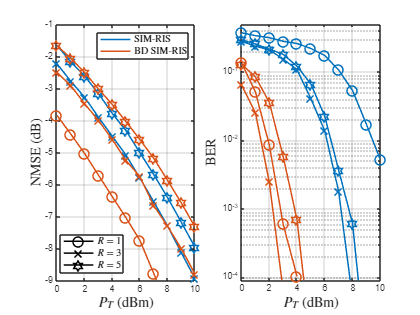

semilogy(Pw_user_dBm,BER,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on

clear
load("MAIN_SIM_5_layers.mat")

% BER PLOT =====================================================================================================
subplot(1,2,2);

% \nu = 1
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#0072BD','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
hold on

% --BD -------------------------------

clear
load("MAIN_BD_1_layer.mat")

% \nu =  2
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"o",'MarkerSize',10);
hold on

clear
load("MAIN_BD_3_layer.mat")

% \nu =  2
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"x",'MarkerSize',10);
hold on

clear
load("MAIN_BD_5_layer.mat")

% \nu =  2
BER = (BerVec(2,:));
semilogy(Pw_user_dBm,BER,'Color','#D95319','LineStyle','-','LineWidth',1.5,'Marker',"hexagram",'MarkerSize',10);
hold on

% ------------------------------------------------------------------------------------------------------
% axis labels
xlabel('$P_T$ (dBm)','Interpreter','latex','FontSize',14);
ylabel('BER','Interpreter','latex','FontSize',14);
ylim([9*10^-5 0.5]);
xlim([0 10]);
xticks(0:2:10)
% legend('Initial','$\nu = 1$','$\nu = 2$','$\nu = 3$','benchmark','Interpreter','latex','FontSize',10)
grid on